%this is the code to calculate AIs in the set up for the old arena with 10
%segments with 1 fly each.
expmt.data.time

ans =   230379×1 RawDataField array with properties:

          raw: [230379×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/DATA/10_well/mated_females/CantonS/03-03-2022-16-19-19__Basic_Tracking_1-10_Day1/raw_data/03-03-2022-16-19-19__time.bin'
          fID: 4
          dim: [230379 1]
    precision: 'single'


reset(expmt.data.time)

ans =   230379×1 RawDataField array with properties:

          raw: [230379×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/DATA/10_well/mated_females/CantonS/03-03-2022-16-19-19__Basic_Tracking_1-10_Day1/raw_data/03-03-2022-16-19-19__time.bin'
          fID: 4
          dim: [230379 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1


interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw(); 
centroids = centroids(1:3600,:,:)

centroids = 3600×2×10 single array
centroids(:,:,1) =

       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
   41.4110  478.1735
   40.4092  469.3977
   45.5960  458.3504
   55.9844  437.4889
   55.9844  437.4889
   67.3289  399.6316
   71.1697  400.7873
   81.7341  397.2386
   96.5293  394.7590
  104.8517  395.6629
  116.0138  394.8142
  130.4106  395.0459
  147.7512  392.1185
  160.6261  395.0344
  177.5766  391.7488
  197.5684  394.0826
  197.5684  394.0826
  242.0408  390.0168
  244.3908  394.5849
  246.1593  386.9262
  251.7904  382.7537
  263.5427  379.7961
  280.7164  379.6404
  299.9616  377.3972
  318.1737  376.1288
  327.5862  376.0282
  327.7349  376.8257
  327.8050  375.6750
  324.0638  374.8138
  324.6897  374.3399
  324.5000  374.2079
  324.5490  374.1519
  324.3655  372.5229
  324.5591  373.1136
  324.3229  372.9193
  324.4430  372.9211
  324.4459  372.9957
  324.3830  372.9617
  324.3234  372.7915
  324.4017  372.6987
  324.6217  372.9565


a = expmt.meta.roi

a = struct with fields:
           mode: 'grid'
          shape: {10×1 cell}
            vec: [10×4×2 double]
            row: [10×1 double]
            col: [10×1 double]
           grid: [10×1 double]
        corners: [10×4 double]
         bounds: [10×4 double]
        centers: [10×2 double]
    orientation: [10×1 logical]
          tform: {10×1 cell}
             im: [2048×2048 uint8]
              n: 10
         pixIdx: {10×1 cell}
           mask: [2048×2048 logical]
     num_traces: [10×1 double]
       cam_dist: [10×1 double]



out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:})

out = 36000×2 single matrix
	1.0e+03 *

       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
    0.0414    0.4782
    0.0404    0.4694
    0.0456    0.4584
    0.0560    0.4375
    0.0560    0.4375
    0.0673    0.3996


x = out(:, 1);
y = out(:, 2);

%centres 1-10 corresponding to each of the 10 segments of the arena.
xcentre1= (a.centers(1,1))

xcentre1 = 200.4935

xcentre2= (a.centers(2,1))

xcentre2 = 610.9294

xcentre3= (a.centers(3,1))

xcentre3 = 1.0214e+03

xcentre4= (a.centers(4,1))

xcentre4 = 1.4318e+03

xcentre5= (a.centers(5,1))

xcentre5 = 1.8422e+03

xcentre6= (a.centers(6,1))

xcentre6 = 200.4935

xcentre7= (a.centers(7,1))

xcentre7 = 610.9294

xcentre8= (a.centers(8,1))

xcentre8 = 1.0214e+03

xcentre9= (a.centers(9,1))

xcentre9 = 1.4318e+03

xcentre10= (a.centers(10,1))

xcentre10 = 1.8422e+03

ycentre1 = (a.centers(1,2))

ycentre1 = 536.5327

ycentre2 = (a.centers(2,2))

ycentre2 = 536.5327

ycentre3 = (a.centers(3,2))

ycentre3 = 536.5327

ycentre4 = (a.centers(4,2))

ycentre4 = 536.5327

ycentre5 = (a.centers(5,2))

ycentre5 = 536.5327

ycentre6 = (a.centers(6,2))

ycentre6 = 958.6714

ycentre7 = (a.centers(7,2))

ycentre7 = 958.6714

ycentre8 = (a.centers(8,2))

ycentre8 = 958.6714

ycentre9 = (a.centers(9,2))

ycentre9 = 958.6714

ycentre10 = (a.centers(10,2))

ycentre10 = 958.6714

%We assign a value of 0 to the traces which occur in the middle of each segment
%(i.e., the traces not above either patch of agarose)
out(x>xcentre1 - 50 & x<xcentre1 + 50 & y<450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre2 - 50 & x<xcentre2 + 50 & y<450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre3 - 50 & x<xcentre3 + 50 & y<450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre4 - 50 & x<xcentre4 + 50 & y<450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre5 - 50 & x<xcentre5 + 50 & y<450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre6 - 50 & x<xcentre6 + 50 & y>450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre7 - 50 & x<xcentre7 + 50 & y>450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre8 - 50 & x<xcentre8 + 50 & y>450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre9 - 50 & x<xcentre9 + 50 & y>450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


out(x>xcentre10 - 50 & x<xcentre10 + 50 & y>450,3)=0

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375         0
    0.0560    0.4375         0
    0.0673    0.3996         0


%Here we asign values to each trace which is above a patch of agarose,
%values 1 and 2 corresponding to the two patches in segment 1, 3 and 4 
%corresponding to the patches in segment 2, etc...
out(x<xcentre1-50 & y<450,3)=1

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre1+50 & x<200 & y<450,3)=2

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>200 & x<xcentre2-50 & y<450,3)=3

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre2+50 & x<400 & y<450,3)=4

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>400 & x<xcentre3-50 & y<450,3)=5

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre3+50 & x<625 & y<450,3)=6

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>625 & x<xcentre4-50 & y<450,3)=7

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre4+50 & x<825 & y<450,3)=8

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>825 & x<xcentre5-50 & y<450,3)=9

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre5+50 & y<450,3)=10

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782         0
    0.0404    0.4694         0
    0.0456    0.4584         0
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010



out(x<xcentre6-50 & y>450,3)=11

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre6+50 & x<200 & y>450,3)=12

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>200 & x<xcentre7-50 & y>450,3)=13

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre7+50 & x<400 & y>450,3)=14

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>400 & x<xcentre8-50 & y>450,3)=15

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre8+50 & x<625 & y>450,3)=16

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>625 & x<xcentre9-50 & y>450,3)=17

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre9+50 & x<825 & y>450,3)=18

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>825 & x<xcentre10-50 & y>450,3)=19

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


out(x>xcentre10+50 & y>450,3)=20

out = 36000×3 single matrix
	1.0e+03 *

       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
    0.0414    0.4782    0.0110
    0.0404    0.4694    0.0110
    0.0456    0.4584    0.0110
    0.0560    0.4375    0.0010
    0.0560    0.4375    0.0010
    0.0673    0.3996    0.0010


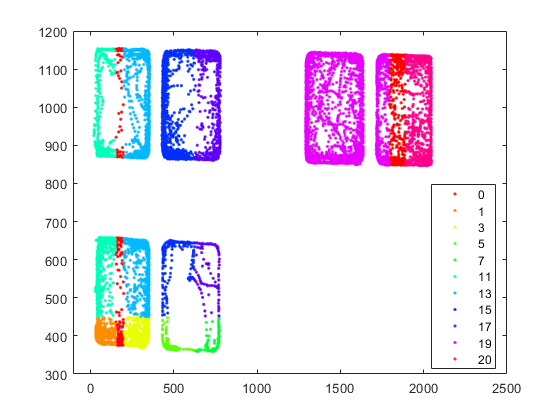


T = array2table(out);

%Remove NaNs
T=T(~any(ismissing(T),2),:);
%plotting
gscatter(T.out1, T.out2, T.out3)

%getting the count (number of traces) for each agarose patch, where C1 and
% are the two patches of segment 1 etc...
GC = groupcounts(T,'out3');
C1 = table2array(GC(2,2))

C1 = 720

C2 = table2array(GC(3,2))

C2 = 996

C3 = table2array(GC(4,2))

C3 = 2842

C4 = table2array(GC(5,2))

C4 = 235

C5 = table2array(GC(6,2))

C5 = 1180

C6 = table2array(GC(7,2))

C6 = 3934

C7 = table2array(GC(8,2))

C7 = 2454

C8 = table2array(GC(9,2))

C8 = 1179

C9 = table2array(GC(10,2))

C9 = 4441

C10 = table2array(GC(11,2))

C10 = 1635

C11 = table2array(GC(12,2))

Row index exceeds table dimensions.

C12 = table2array(GC(13,2))
C13 = table2array(GC(14,2))
C14 = table2array(GC(15,2))
C15 = table2array(GC(16,2))
C16 = table2array(GC(17,2))
C17 = table2array(GC(18,2))
C18 = table2array(GC(19,2))
C19 = table2array(GC(20,2))
C20 = table2array(GC(21,2))

%calculating the AIs for each patch in each segment. As there are only two
%patches in each segment, the AIs for each patch in a segment is equal to
%the negative value of the other patch in the segment.
AI1=(C1-C2)/(C1+C2)
AI2=(C2-C1)/(C1+C2)
AI3=(C3-C4)/(C3+C4)
AI4=(C4-C3)/(C3+C4)
AI5=(C5-C6)/(C5+C6)
AI6=(C6-C5)/(C5+C6)
AI7=(C7-C8)/(C7+C8)
AI8=(C8-C7)/(C7+C8)
AI9=(C9-C10)/(C9+C10)
AI10=(C10-C9)/(C9+C10)
AI11=(C11-C12)/(C11+C12)
AI12=(C12-C11)/(C11+C12)
AI13=(C13-C14)/(C13+C14)
AI14=(C14-C13)/(C13+C14)
AI15=(C15-C16)/(C16+C15)
AI16=(C16-C15)/(C16+C15)
AI17=(C17-C18)/(C18+C17)
AI18=(C18-C17)/(C18+C17)
AI19=(C19-C20)/(C20+C19)
AI20=(C20-C19)/(C20+C19)
